clear

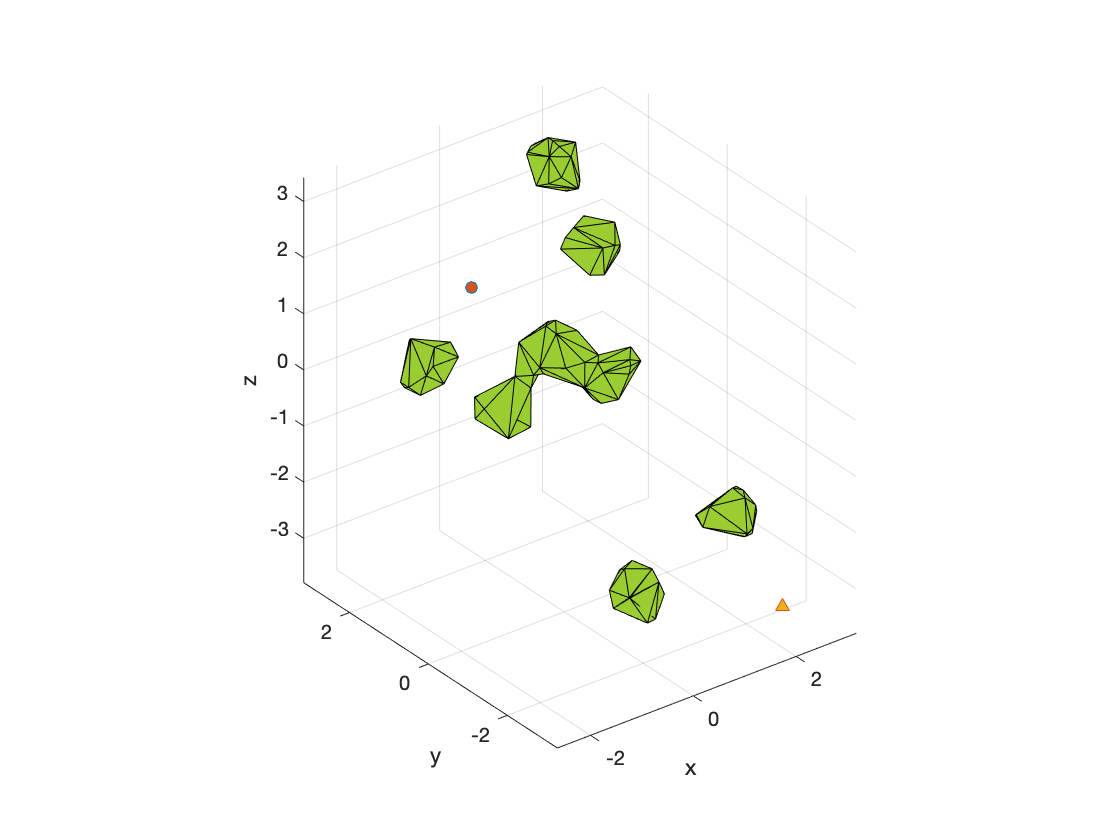

% RRT:
KDRRT = CLS_KDRRTStar;
KDRRT.IsDEBUG = 1;
KDRRT.NN_method = 'KDTree';
KD_RRT_Star_Time = [];
KD_iter = [];

% parfor i = 1:1000
    % Build Obstacles:
    [boundaries, n_obs_vertices, obs_vertices] = Obstacles(10);
    hold on
    [KDRRT.r_start, KDRRT.r_end, KDRRT.search_boundaries] = StartEnd_Coor(boundaries);

    
    tic;
    [path, ite] = KDRRT.RRT_Star()

IsDEBUG = 1

Undefined function 'Reached_Goal' for input arguments of type 'struct'.

Error in CLS_KDRRTStar/RRT_Star (line 43)
            while Reached_Goal(nodes, pt_goal, r, NN_method) == 0 && i <= max_iter

    time = toc;
    
    KD_iter = [KD_iter, ite];
    KD_RRT_Star_Time = [KD_RRT_Star_Time, time];
% end
hold off
scatter(KD_iter, KD_RRT_Star_Time)
xlabel('Number of iterations')
ylabel('RRT* runtime')